%Lab 1
clear
clc

## Task 1 Frequency Resolution

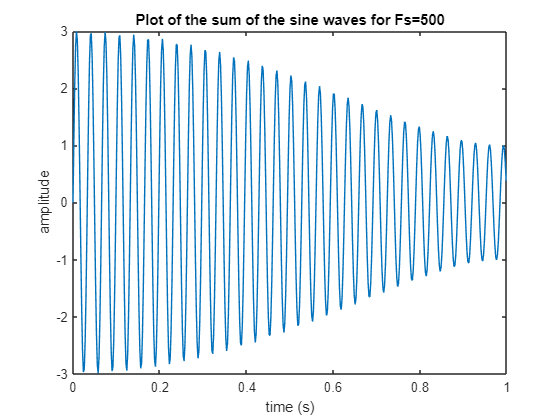

fs = 500; % sampling frequency
N = 500; % number of samples
t = (0:N-1)/fs; % time range
f1 = 30; %frequency one
f2 = 30.5; %frequency two
a1 = 1; % amplitude one
a2 = 2; % amplitude two
y = a1*sin(2*pi*f1*t) + a2*sin(2*pi*f2*t); % the created sine wave Phenomena is Beating add to report
figure(1)
plot(t,y)
xlabel('time (s)')
ylabel('amplitude')
title('Plot of the sum of the sine waves for Fs=500')

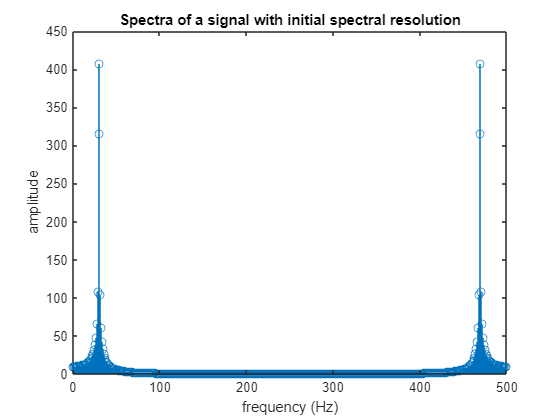

% Creating the fourier transform
Y = fft(y);
df = fs/N; % frequency resolution
fv = (0:N-1)*df; % frequency vector
Nf = (abs(Y)/N*2);
figure(2)
stem(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
title('Spectra of a signal with initial spectral resolution')

The obtained plot showcases two major areas of interest, but for the sake of analysis we are only interested in the frequencies up to nyquist frequency fn=fs/2. 

Additionally we should scale the x axis to further showcase the frequencies of interest which lie between 29-32Hz.

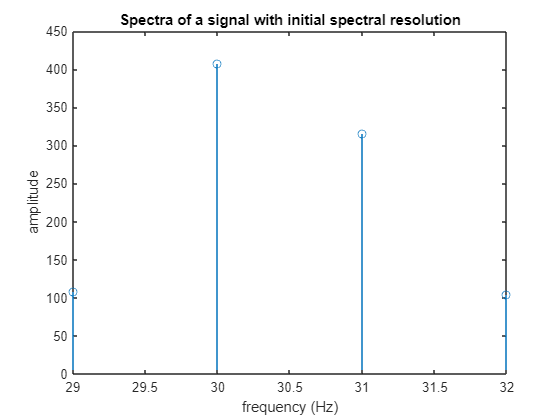

figure()
stem(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
title('Spectra of a signal with initial spectral resolution')
xlim([29,32]) %limiting the plot to the region of interest

It is known that the spectra of the signal should showcase all the main frequency components contained within the signal. In our case there should be two observable 

peaks at 30Hz and 30,5Hz corresponding to the two sine waves that the signal was composed of. Instead of the expected result we can see four peeks at 29, 30, 31 and 32Hz. 

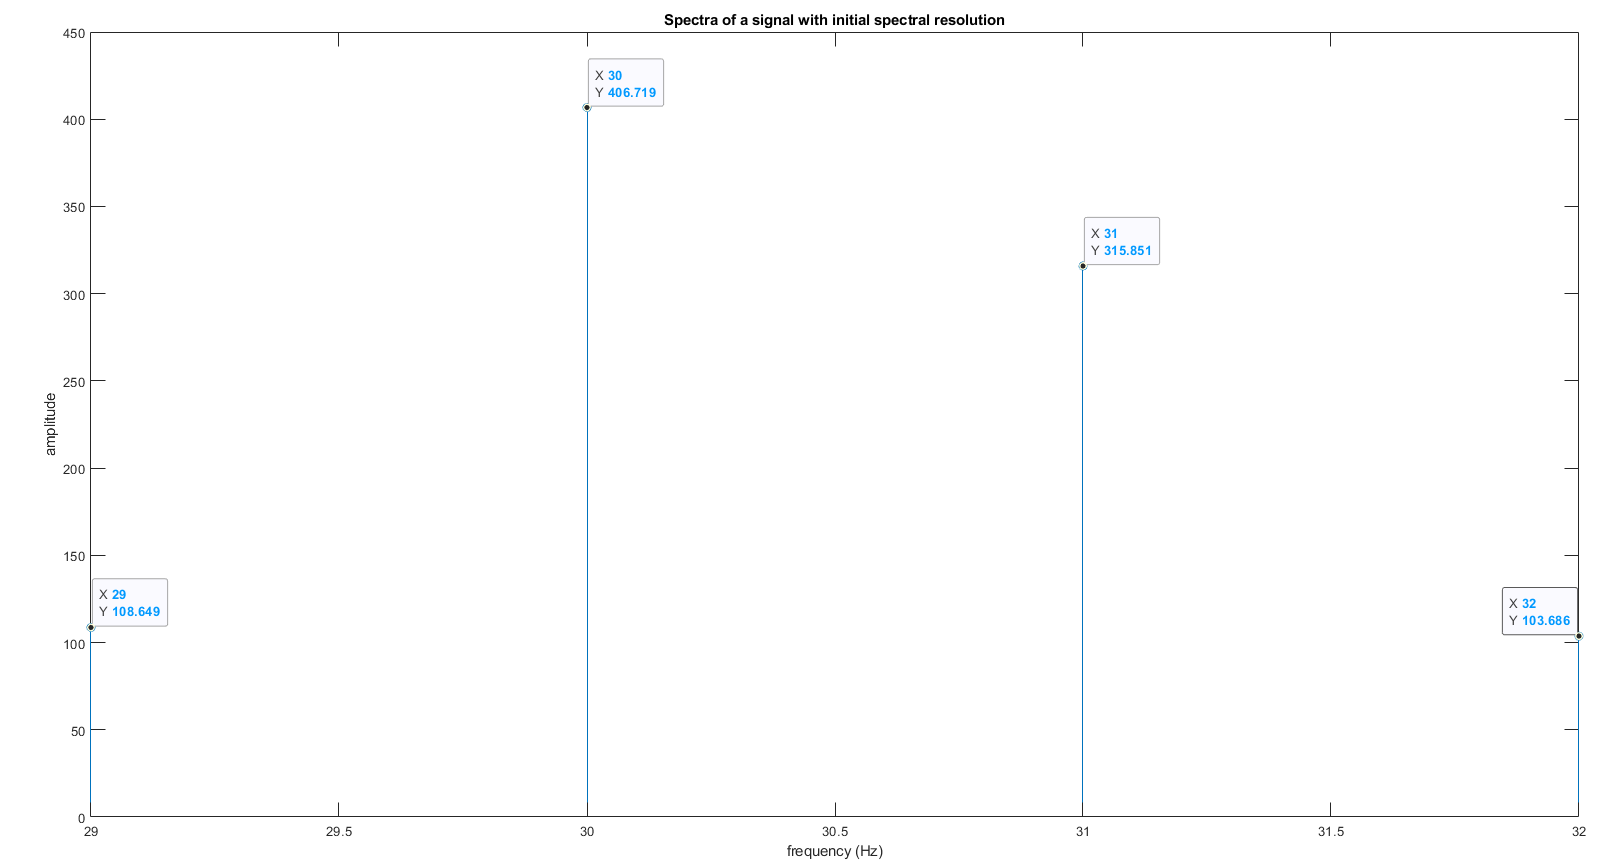

fig. resultant peaks

Those additional peaks are known as sidelobes and they occur whenever there is spectral leakage present in the system. 

Spectral leakage in the fft is caused by the mismatch between desired and chosen frequency (spectral) resolution. We can therefore get rid of it by 

modifying the frequency resolution. We will do it in the next part of the code:

The spectral resolution is the sampling rate at which the sensor (in case of a physical system) collects the informations about the observed system. 

It is expressed by the following equation: dF=Fs/N, where Fs is sampling frequency and N is number of samples.

As a result the spectral resolution increases whenever dF decreases ie. when the number of samples increases).

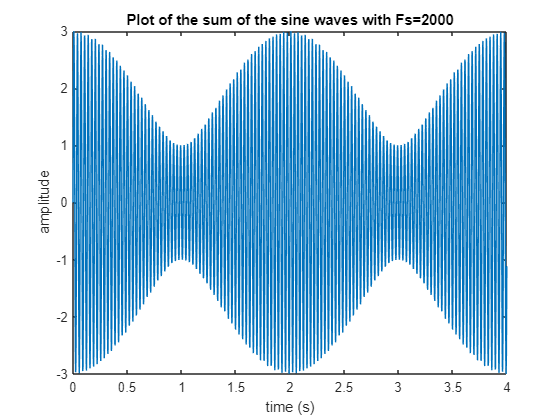

fs = 500; % sampling frequency
N = 2000; % number of samples
t = (0:N-1)/fs; % time range
f1 = 30; %frequency one
f2 = 30.5; %frequency two
a1 = 1; % amplitude one
a2 = 2; % amplitude two
y = a1*sin(2*pi*f1*t) + a2*sin(2*pi*f2*t); % the created sine wave Phenomena is Beating add to report
figure(1)
plot(t,y)
xlabel('time (s)')
ylabel('amplitude')
title('Plot of the sum of the sine waves with Fs=2000')

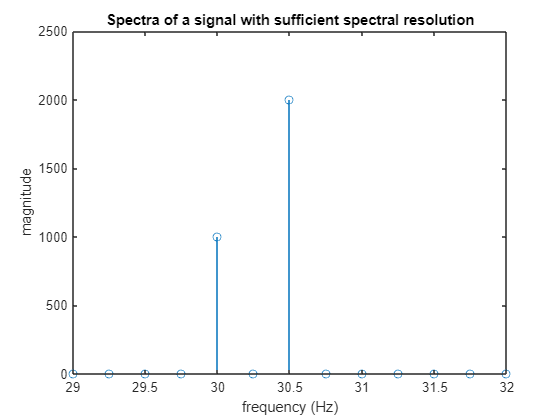

% Creating the fourier transform
Y = fft(y);
df = fs/N; % frequency resolution
fv = (0:N-1)*df; % frequency vector
Nf = (abs(Y)/N*2);
figure(2)
stem(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('magnitude')
title('Spectra of a signal with sufficient spectral resolution')
xlim([29,32]) %limiting the plot to the region of interest

After increasing the spectral resolution we can clearly observe that the new spectra presents us with exactly 2 peaks at 30 and 30,5Hz which is the desired output. 

In summary, spectral leakage results from insufficient spectral resolution, causing inaccuracies when analyzing signals. The leakage can be mitigated by modifying 

spectral resolution or by aplying more advanced techniques such as windows.

## Task 2 Resampling

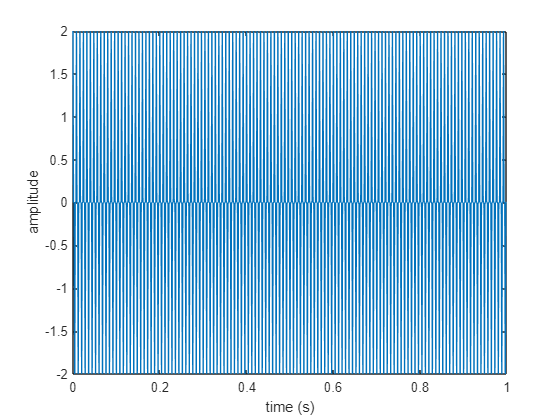

% First Signal MAIN COMMENT The frequencies add up due to the mirroring
% with incorrect samples
fs = 1000; % sampling frequency
N = 1000; % number of samples
t = (0:N-1)/fs; % time range
f1 = 125; %frequency one
f2 = 375; %frequency two
y = cos(2*pi*f1*t) + cos(2*pi*f2*t); % the created sine wave Phenomena is Beating add to report
figure(1)
plot(t,y)
xlabel('time (s)')
ylabel('amplitude')

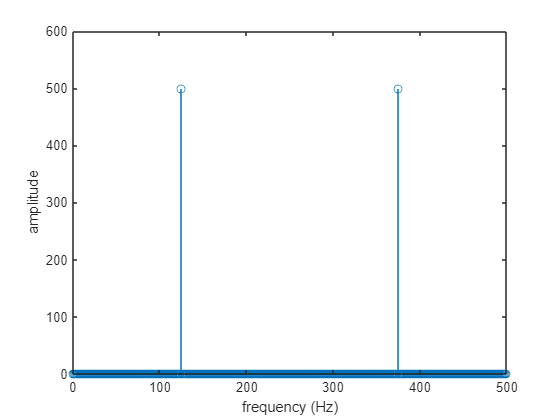

% Creating the fourier transform
Y = fft(y);
N = length(Y);
df = fs/N; % frequency resolution
fv = (0:N-1)*df; % frequency vector
Nf = (abs(Y)/N*2);
figure(2)
stem(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,500])

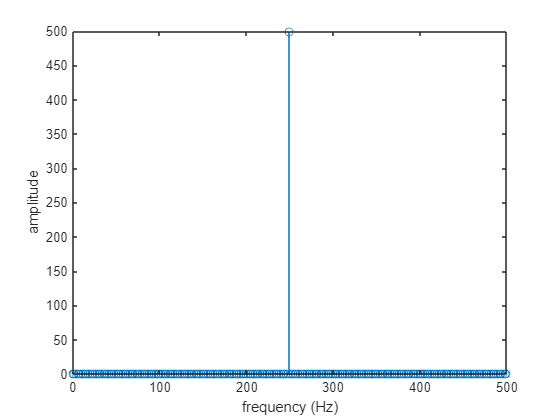


% Subsampled Signal
Y1 = (y(1:2:end));
% Creating the fourier transform
Y = fft(Y1);
N = length(Y);
df = fs/N; % frequency resolution
fv = (0:N-1)*df; % frequency vector
Nf = (abs(Y)/N*2);
figure(2)
stem(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,500])

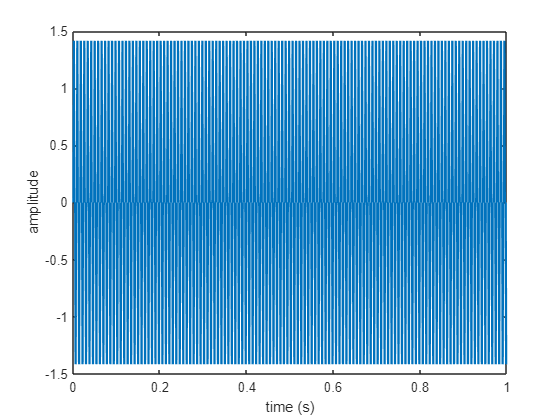


% Part a
% First Signal
fs = 1000; % sampling frequency
N = 1000; % number of samples
t = (0:N-1)/fs; % time range
f1 = 125; %frequency one
f2 = 375; %frequency two
y1 = sin(2*pi*f1*t) + sin(2*pi*f2*t); % the created sine wave Phenomena is Beating add to report
figure(1)
plot(t,y1)
xlabel('time (s)')
ylabel('amplitude')

% Creating the fourier transform
Y = fft(y);
N = length(Y);
df = fs/N; % frequency resolution
fv = (0:N-1)*df; % frequency vector
Nf = (abs(Y)/N*2);
figure(2)
stem(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,500])


% Subsampled Signal
Y1 = (y(1:2:end));
% Creating the fourier transform
Y = fft(Y1);
N = length(Y);
df = fs/N; % frequency resolution
fv = (0:N-1)*df; % frequency vector
Nf = (abs(Y)/N*2);
figure(2)
stem(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,500])

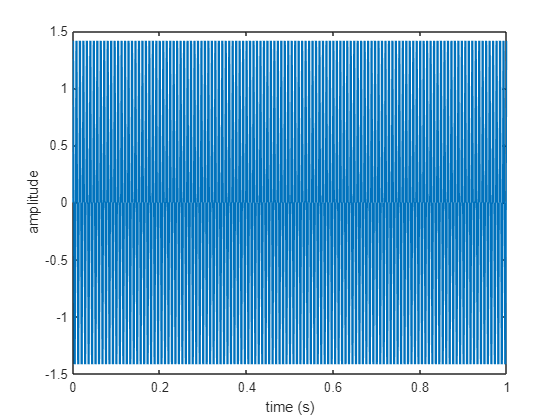


% Part b
% First Signal
fs = 1000; % sampling frequency
N = 1000; % number of samples
t = (0:N-1)/fs; % time range
f1 = 125; %frequency one
f2 = 375; %frequency two
y = cos(2*pi*f1*t) - cos(2*pi*f2*t); % the created sine wave Phenomena is Beating add to report
figure(1)
plot(t,y)
xlabel('time (s)')
ylabel('amplitude')

% Creating the fourier transform
Y = fft(y);
N = length(Y);
df = fs/N; % frequency resolution
fv = (0:N-1)*df; % frequency vector
Nf = (abs(Y)/N*2);
figure(2)
stem(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,500])

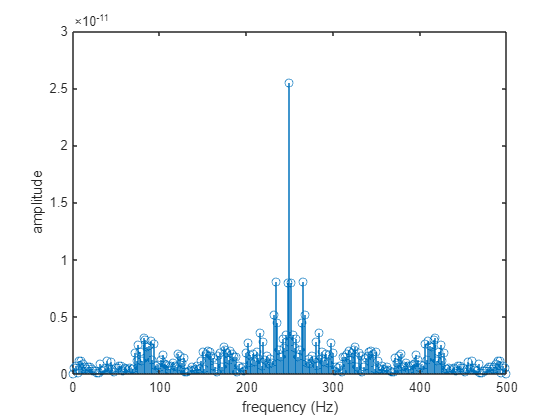


% Subsampled Signal
Y1 = (y(1:2:end));
% Creating the fourier transform
Y = fft(Y1);
N = length(Y);
df = fs/N; % frequency resolution
fv = (0:N-1)*df; % frequency vector
Nf = (abs(Y)/N*2);
figure(2)
stem(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,500])

The beating phenomenon in signal processing occurs when signals with frequencies that are close but not identical are combined, they produce a resultant waveform with a slowly varying amplitude (known as beating). The beat frequency is equal to the difference between the frequencies of the two original signals.

Beating is commonly encountered in audio signals. It results in a distinct rise and fall in intensity, creating a noticeable pulsating effect. In our particular example due to the frequencies being close to each other the phenomenon leads to constructive and destructive interference patterns.

By analyzing beat frequencies, engineers can extract information about the characteristics of the original signals.

## Task 3 Spectral leakage and windowing

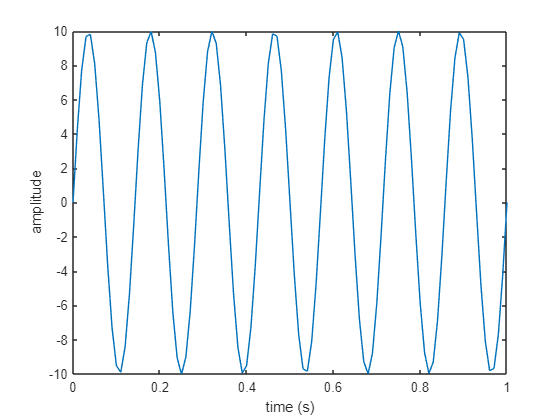

fs = 100; % sampling frequency
N = 101; % number of samples
t = (0:N-1)/fs; % time range
f1 = 7; %frequency one
f2 = 20; %frequency two
a1 = 10; % amplitude one
a2 = 0.02; % amplitude two
y1 = a1*sin(2*pi*f1*t) + a2*sin(2*pi*f2*t); % the created sine wave Phenomena is Beating add to report
figure(1)
plot(t,y1)
xlabel('time (s)')
ylabel('amplitude')

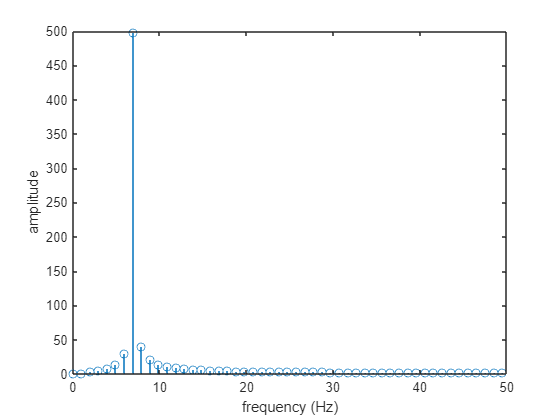


% Creating the fourier transform
Y = fft(y1);
N = length(Y);
df = fs/N; % frequency resolution
fv = (0:N-1)*df; % frequency vector
Nf = (abs(Y)/N*2);
figure(2)
stem(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('amplitude')
xlim([0,50])

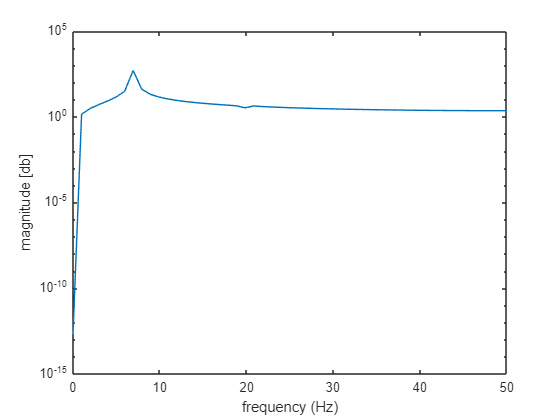


figure(3)
semilogy(fv , abs(Y))
xlabel('frequency (Hz)')
ylabel('magnitude [db]')
xlim([0,50])


% what to do multiply signal by Hann woindow and observe the difference
% after reduction of spectral leakage